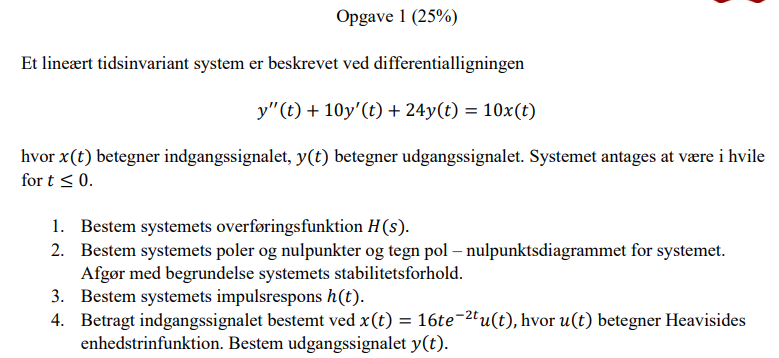

### **1. Bestem systemets overføringsfunktion H(s)**

% Definer nødvendige symbolske variable
syms s t;

% Opgave 1: Bestem systemets overføringsfunktion H(s)
% Koefficienterne for differentialligningen:
% y''(t) + 10y'(t) + 24y(t) = 10x(t)
a = [1, 10, 24];  % Koefficienter for y
b = [10];         % Koefficienter for x

disp('Opgave 1: Overføringsfunktion H(s)');

[num, den, H_forklaring] = ElektroMatBibTrinvis.diffLigningTilOverfoeringsfunktionMedForklaring(b, a);

H_s = poly2sym(num, s) / poly2sym(den, s);
%H_s_str = H_forklaring.resultat;

disp(['H(s) = ', char(H_s)]);

### **2. Bestem poler, nulpunkter og stabilitetsforhold**

disp('Opgave 2: Poler og nulpunkter');
forklaringsOutput = ElektroMatBibTrinvis.analyserDifferentialligningMedForklaring(a);

% Poler:
poler = roots(a);
disp('Poler:');
disp(poler);

% Nulpunkter:
nulpunkter = roots(num);
disp('Nulpunkter:');
disp(nulpunkter);

### **3. Bestem systemets impulsrespons h(t)**

disp('Opgave 3: Impulsrespons h(t)');

[h_t, h_forklaring] = ElektroMatBibTrinvis.inversLaplaceMedForklaring(H_s, s, t);

disp(['h(t) = ', char(h_t)]);

### **4. Bestem udgangssignalet y(t)**

disp('Opgave 4: Udgangssignal y(t)');

% Definer indgangssignalet x(t)
x_t = 16*t*exp(-2*t);

% Beregn Laplace-transformationen af x(t)
X_s = laplace(x_t, t, s);

% Beregn udgangssignalet y(t)
[y_t, y_forklaring] = ElektroMatBibTrinvis.beregnUdgangssignalMedForklaring(H_s, X_s, s, t);
disp(['y(t) = ', char(y_t)]);

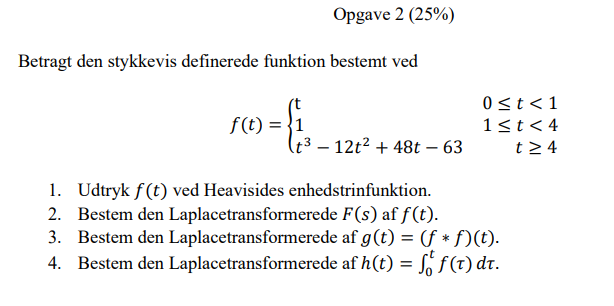

### 1. Udtryk f(t) ved Heavisides enhedstrinfunktion

% Definér symbolske variable
syms t

% Definér de tre stykker af funktionen
f1 = t;             % 0 ≤ t < 1
f2 = 1;             % 1 ≤ t < 4
f3 = t^3 - 12*t^2 + 48*t - 63;  % t ≥ 4

% Definér grænserne for intervallerne
graenser = [0, 1, 4, inf];

% Kald den nye funktion
[f_t, forklaring] = ElektroMatBibTrinvis.stykkevisFunktionMedForklaring({f1, f2, f3}, graenser, t);

===== STYKKEVIS FUNKTION MED HEAVISIDES ENHEDSTRINFUNKTION =====
 
TRIN 1: Identificer den stykkevis definerede funktion
Vi starter med at identificere den stykkevis definerede funktion.
   f(t) = t for 0 ≤ t < 1
1 for 1 ≤ t < 4
48*t - 12*t^2 + t^3 - 63 for t ≥ 4
 
TRIN 2: Introduktion til Heavisides enhedstrinfunktion
Heavisides enhedstrinfunktion u(t-a) er defineret som:
u(t-a) = 0 for t < a
u(t-a) = 1 for t ≥ a
   Vi bruger denne til at skifte mellem de forskellige funktionsdele.
 
TRIN 3: Konverter den stykkevis funktion til Heaviside-notation
Vi udtrykker hver del af funktionen med Heaviside-funktioner:
 
TRIN 4: Del 1: Funktion på intervallet [0, 1)
Vi udtrykker f(t) = t på intervallet [0, 1) som:
   t·[u(t-0) - u(t-1)]
 
TRIN 5: Del 2: Funktion på intervallet [1, 4)
Vi udtrykker f(t) = 1 på intervallet [1, 4) som:
   1·[u(t-1) - u(t-4)]
 
TRIN 6: Del 3: Funktion på intervallet [4, Inf)
Vi udtrykker f(t) = 48*t - 12*t^2 + t^3 - 63 på intervallet [4, Inf) som:
   48*t - 12*t^2 + t


% Vis resultatet
disp('f(t) udtrykt med Heavisides enhedstrinfunktion:');

f(t) udtrykt med Heavisides enhedstrinfunktion:


disp(f_t);

$$\mathrm{heaviside}\left(t-1\right)-\mathrm{heaviside}\left(t-4\right)-t\,\left(\mathrm{heaviside}\left(t-1\right)-\mathrm{heaviside}\left(t\right)\right)+\mathrm{heaviside}\left(t-4\right)\,\left(t^{3}-12\,t^{2}+48\,t-63\right)$$

### **2. Bestem den Laplacetransformerede F(s) af f(t)**

% Beregn Laplacetransformationen
syms s
[F_s, laplace_forklaring] = ElektroMatBibTrinvis.laplaceMedForklaring(f_t, t, s);

===== LAPLACETRANSFORMATION =====
 
TRIN 1: Identificer den oprindelige funktion
Vi starter med at identificere den funktion, der skal transformeres.
   f(t) = heaviside(t - 1) - heaviside(t - 4) - t*(heaviside(t - 1) - heaviside(t)) + heaviside(t - 4)*(48*t - 12*t^2 + t^3 - 63)
 
TRIN 2: Beregn Laplacetransformationen symbolsk
Vi beregner integralet symbolsk:
   F(s) = exp(-4*s)*((48*((4*s)/3 + 1))/s^2 - (96*(2*s + 1))/s^2 + (48*((43*s)/16 + 1))/s^2 + 6/s^4) - exp(-s)/s^2 - exp(-4*s)/s + 1/s^2
 
RESULTAT:
   F(s) = exp(-4*s)*((48*((4*s)/3 + 1))/s^2 - (96*(2*s + 1))/s^2 + (48*((43*s)/16 + 1))/s^2 + 6/s^4) - exp(-s)/s^2 - exp(-4*s)/s + 1/s^2
 
===== AFSLUTTET: LAPLACETRANSFORMATION =====
 


disp('Laplacetransformation F(s):');

Laplacetransformation F(s):



F_s_simplify = simplify(F_s);
disp(F_s_simplify);

$$\frac{6\,{\mathrm{e}}^{-4\,s}-s^{2}\,{\mathrm{e}}^{-s}+s^{2}}{s^{4}}$$

### **3. Bestem den Laplacetransformerede af g(t) = (f * f)(t)**

% Fra delopgave 2 har vi F(s)
% Brug foldningssætningen: L{f*f} = F(s)·F(s)
[G_s, forklaring3] = ElektroMatBibTrinvis.foldningssaetningMedForklaring(F_s, F_s, s, t);

===== FOLDNINGSSÆTNINGEN FOR LAPLACETRANSFORMATION =====
 
TRIN 1: Identificer Laplacetransformationerne
Vi starter med de to Laplace-transformerede funktioner.
   F(s) = exp(-4*s)*((48*((4*s)/3 + 1))/s^2 - (96*(2*s + 1))/s^2 + (48*((43*s)/16 + 1))/s^2 + 6/s^4) - exp(-s)/s^2 - exp(-4*s)/s + 1/s^2\nG(s) = exp(-4*s)*((48*((4*s)/3 + 1))/s^2 - (96*(2*s + 1))/s^2 + (48*((43*s)/16 + 1))/s^2 + 6/s^4) - exp(-s)/s^2 - exp(-4*s)/s + 1/s^2
 
TRIN 2: Forklar foldningssætningen
Foldningssætningen siger, at produktet af to Laplacetransformationer svarer til Laplacetransformationen af foldningen af de oprindelige funktioner.
   L{(f * g)(t)} = F(s) · G(s)
 
TRIN 3: Beregn produktet af Laplacetransformationerne
Vi beregner produktet F(s) · G(s).
   H(s) = F(s) · G(s) = exp(-4*s)*((48*((4*s)/3 + 1))/s^2 - (96*(2*s + 1))/s^2 + (48*((43*s)/16 + 1))/s^2 + 6/s^4) - exp(-s)/s^2 - exp(-4*s)/s + 1/s^2 · exp(-4*s)*((48*((4*s)/3 + 1))/s^2 - (96*(2*s + 1))/s^2 + (48*((43*s)/16 + 1))/s^2 + 6/s^4) - exp(-s)/s^2 - 


G_s_simplify = simplify(G_s);
disp(G_s_simplify);

$$\frac{{\mathrm{e}}^{-8\,s}\,{\left(s^{2}\,{\mathrm{e}}^{4\,s}-s^{2}\,{\mathrm{e}}^{3\,s}+6\right)}^{2}}{s^{8}}$$

### 4. Bestem den Laplacetransformerede af h(t) = ∫₀ᵗ f(τ) dτ

% Antag at F_s er resultatet fra delopgave 2
syms s

% Anvend integralteoremet: L{∫₀ᵗ f(τ) dτ} = F(s)/s
H_s = F_s / s;

% Simplificér resultatet
H_s = simplify(H_s);

disp('Delopgave 4:');

Delopgave 4:


disp('Laplacetransformationen af h(t) = ∫₀ᵗ f(τ) dτ:');

Laplacetransformationen af h(t) = ∫₀ᵗ f(τ) dτ:


disp('H(s) = F(s)/s =');

H(s) = F(s)/s =


disp(H_s);

$$\frac{6\,{\mathrm{e}}^{-4\,s}-s^{2}\,{\mathrm{e}}^{-s}+s^{2}}{s^{5}}$$

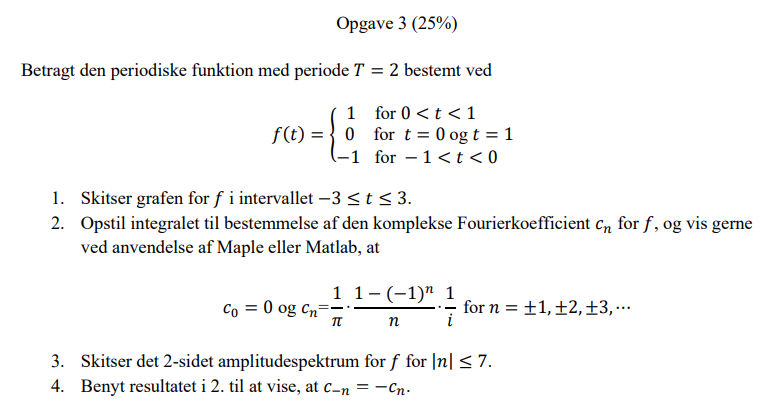

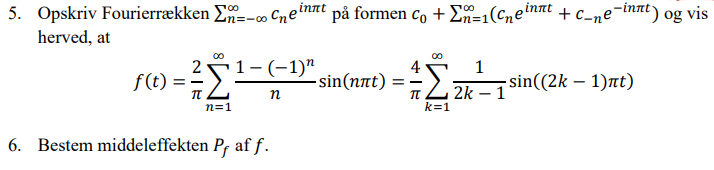

### 1.  Skitser grafen for 𝑓 i intervallet −3 ≤ 𝑡 ≤ 3.

% Start med at oprette symbolske variable
syms t n;
T = 2; % Perioden er givet som T = 2

% Del 1: Vi definerer først funktionen manuelt som vist i opgaven
% f(t) = { 1  for 0 < t < 1
%        { 0  for t = 0 og t = 1
%        { -1 for -1 < t < 0

% Da biblioteket har problemer med at beregne c0, laver vi strukturen manuelt
% Vi ved fra opgaven at c0 = 0 og cn = (1-(-1)^n)/(n*pi*i) for n = ±1, ±2, ±3, ...

% Lav en cn-struktur som biblioteket forventer
cn = struct();
cn.c0 = 0; % c0 er givet som 0 i opgaven

% Beregn koefficienter for positive og negative n
for k = 1:7  % Vi går til |n| ≤ 7 som opgaven beder om
    % For positive n
    cn.(['c' num2str(k)]) = (1-(-1)^k)/(k*pi*1i);
    
    % For negative n
    cn.(['cm' num2str(k)]) = (1-(-1)^(-k))/((-k)*pi*1i);
end

% Del 3: Skitser 2-sidet amplitudespektrum for |n| ≤ 7
% Vi kan bruge parsevalTeoremMedForklaring som automatisk tegner spektrummet
[P, parsevalForklaring] = ElektroMatBibTrinvis.parsevalTeoremMedForklaring(cn, 7);

% Del 4: Verificer at c_{-n} = -c_n
% Vi kan verificere dette direkte fra vores struktur
disp('Verifikation af c_{-n} = -c_n:');
for k = 1:7
    c_pos = cn.(['c' num2str(k)]);
    c_neg = cn.(['cm' num2str(k)]);
    disp(['n = ' num2str(k) ': c_n = ' num2str(c_pos) ', c_{-n} = ' num2str(c_neg)]);
    disp(['Relation: c_{-n} = -c_n er ' ...
          iif(abs(c_neg + c_pos) < 1e-10, 'BEKRÆFTET', 'IKKE BEKRÆFTET')]);
end

% Del 5: Omskriv Fourierrækken til sinusform
% Vi kan bruge fourierRaekkeMedForklaring til at få en approksimation
[f_approx, raekkeForklaring] = ElektroMatBibTrinvis.fourierRaekkeMedForklaring(cn, t, T, 7);

% Del 6: Middeleffekten er allerede beregnet i trin 3
disp(['Middeleffekt Pf = ' num2str(P)]);

% Hjælpefunktion til at vise ja/nej
function result = iif(condition, trueVal, falseVal)
    if condition
        result = trueVal;
    else
        result = falseVal;
    end
end